# **IO781 - AFDX Loopback**

This example shows you how to perform a loopback test with the IO781 AFDX/ARINC664 I/O module, in order to verify the basic protocol communication over the transmit and receive channels.

The IO781 provides an on-board protocol stack that off loads the protocol processing from the host system. A configuration file can be created with Flight Simulyzer and directly used in the Simulink driver block.

The Simulink model features the [IO781 AFDX/ARINC664 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io781_setup), [IO781 Send](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io781_send) and [IO781 Receive](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io781_receive) blocks.

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO781 I/O module installed

- RJ45-Ethernet cable

### Pin Mapping/Connection Diagram/Test Setup

On the I/O module, connect port 0 and port 1 through the Ethernet cable.

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO781_AFDXLoopback';
open_system(modelName);

### Model Description

In the model, two datasets are packed into an ARINC664 implicit message and are transmitted through port 1. The message contains two datasets and their corresponding functional status bytes. For both datasets, the functional status is set to normal operation (3). The other options are no data (0), functional test (12) and no computed data (48). Dataset 1 contains a sine wave and dataset 2 a 32-bit counter.

On the receiving side, the data is read from port 5 and split up into the defined datasets. A [Selector](https://www.mathworks.com/help/simulink/slref/selector.html) and a [Byte Unpacking](https://www.mathworks.com/help/slrealtime/io_ref/byteunpacking.html) block are used to extract the original signals.

The input port is configured as follows by using Flight Simulyzer (Refer to the [IO781 Usage Notes](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io781_usage_notes) for more information):

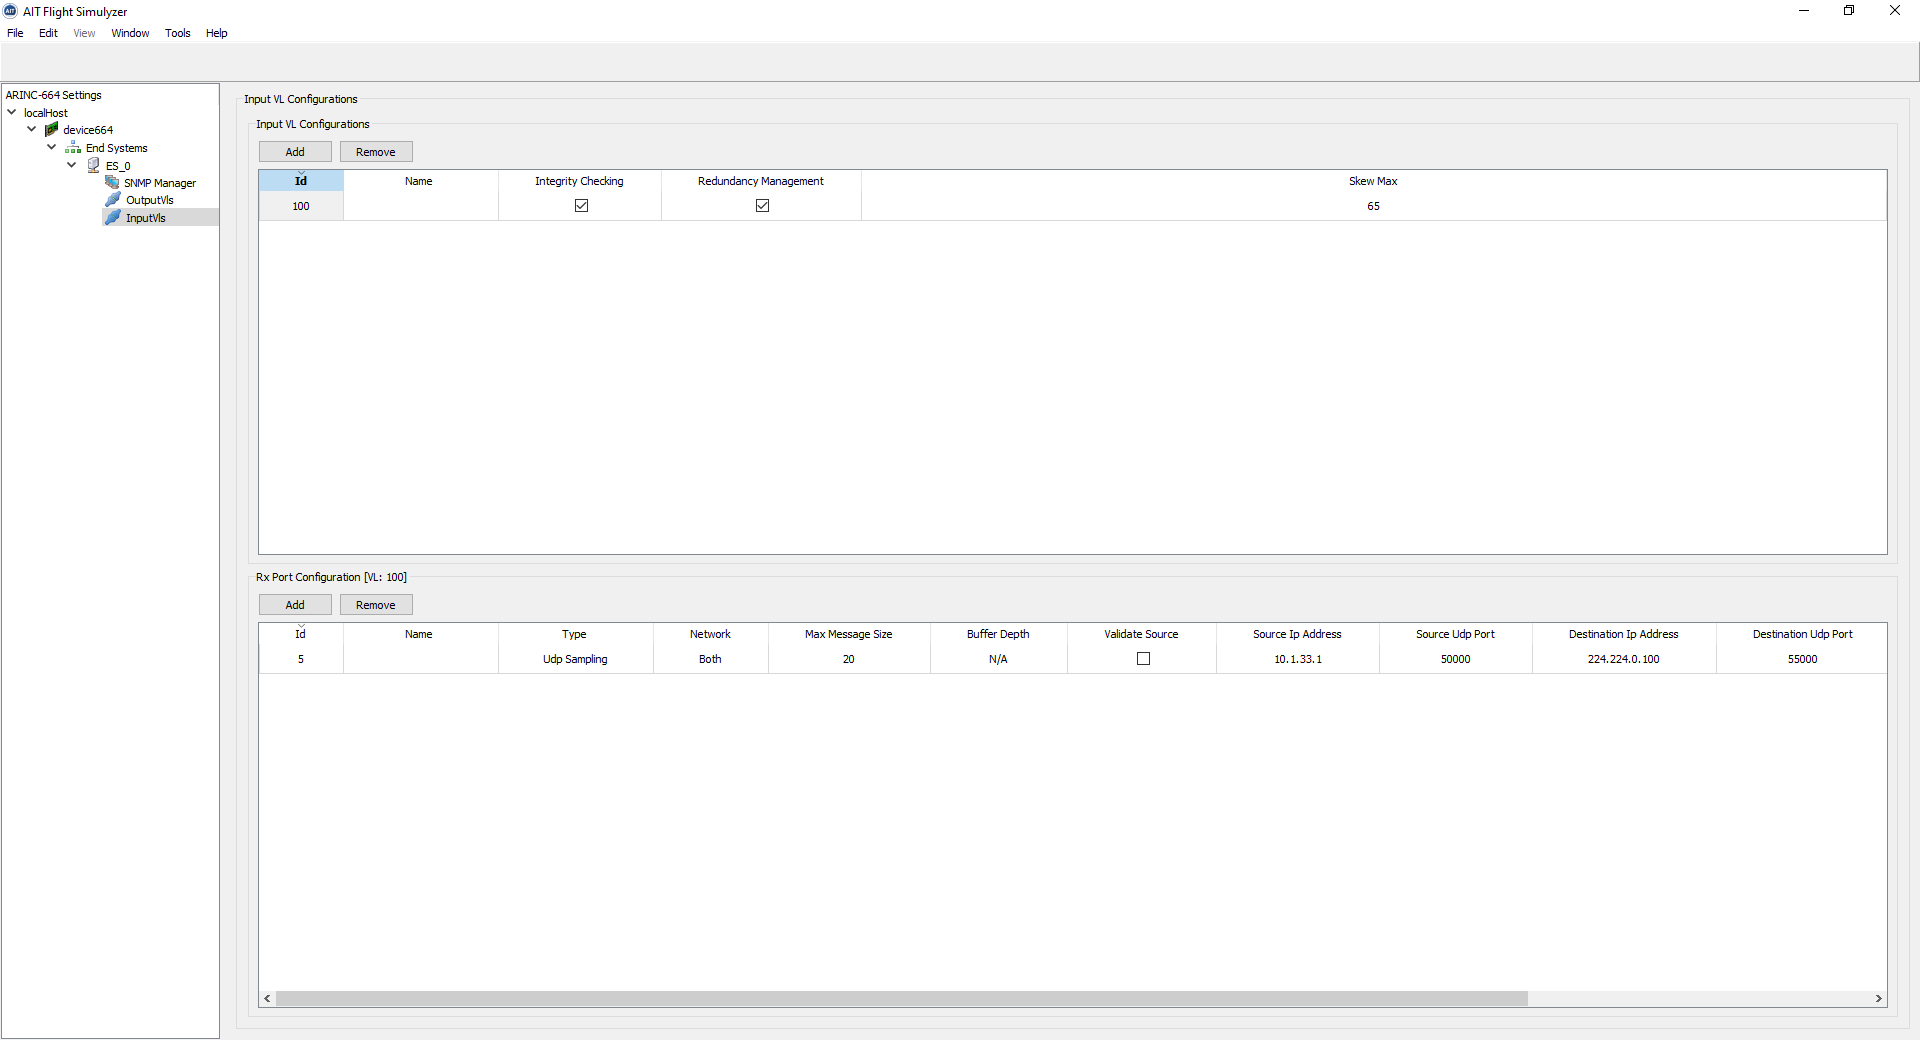

The output port is configured as follows:

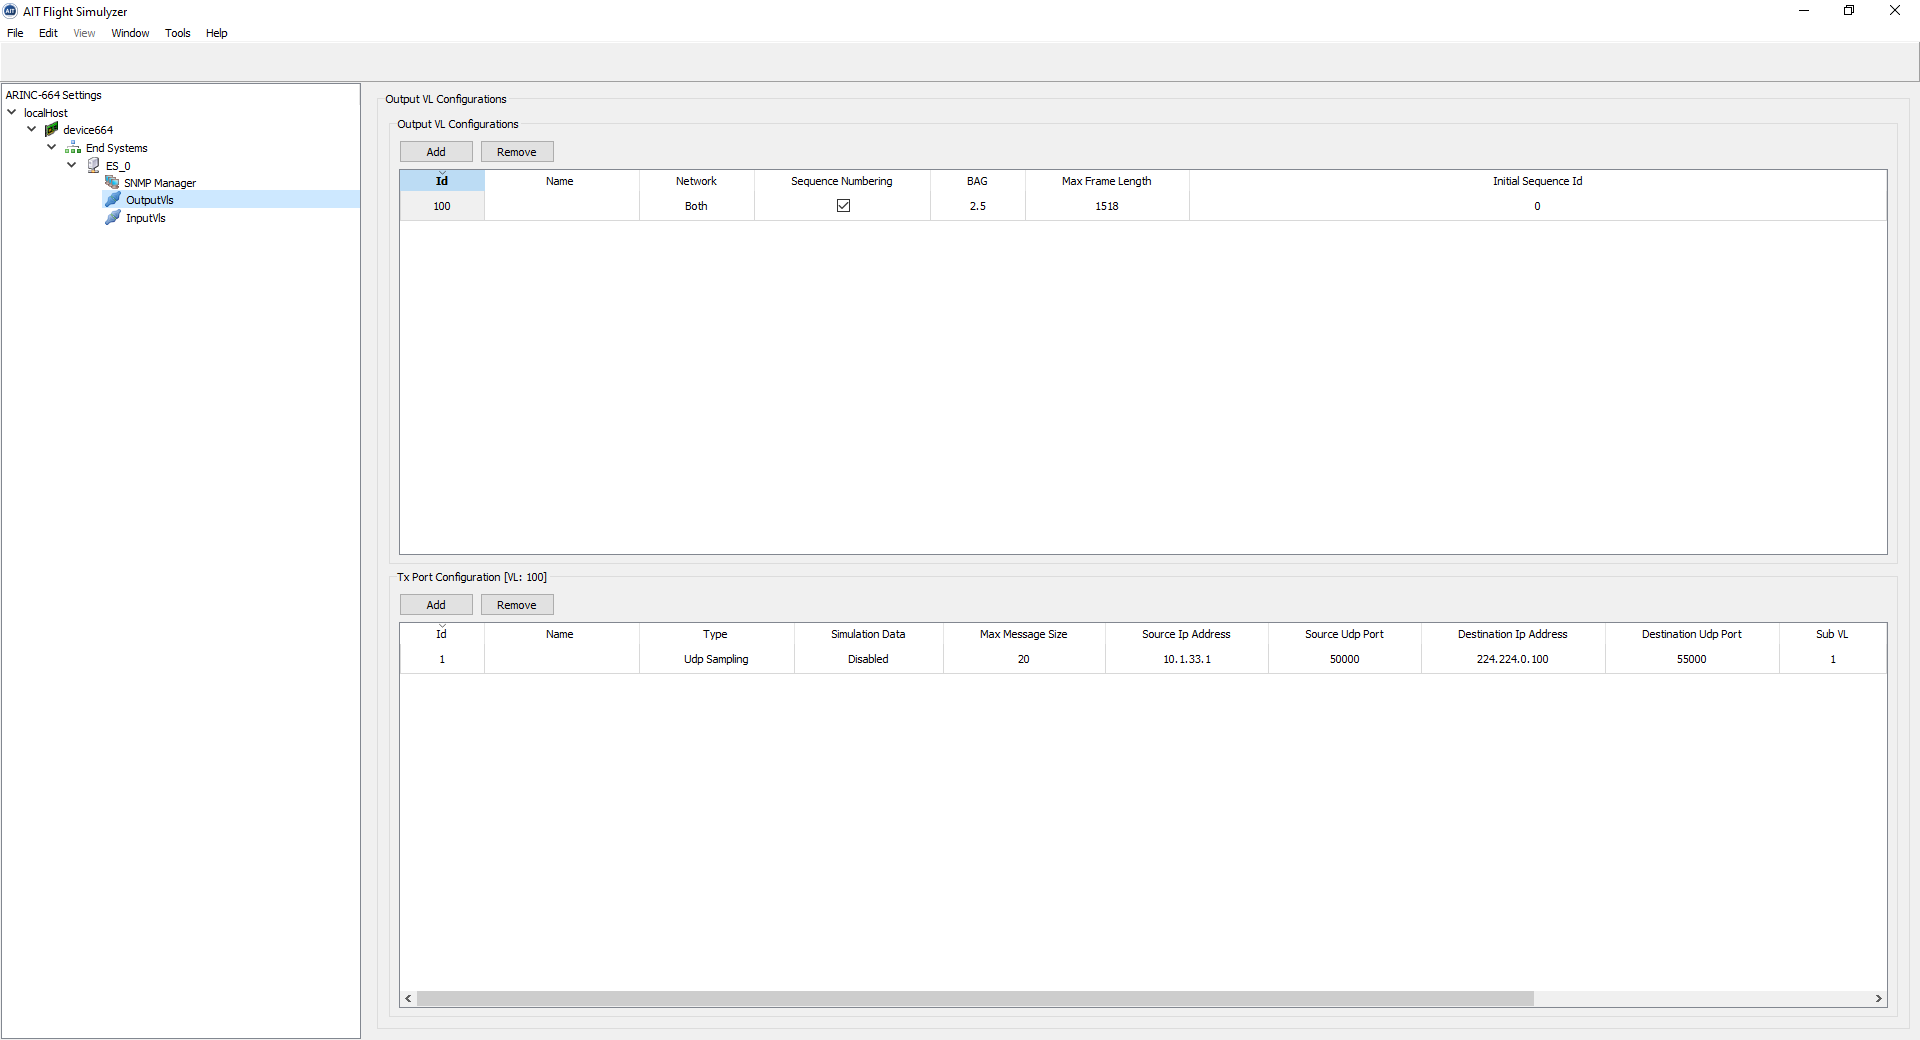

After adapting the port configuration, the configuration file must be generated and linked in the [IO781 Setup](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io781_setup) block. The configuration file is already generated and available in this example (IO781_Config.adc).

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName); % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName, 'SimulationMode', 'external') % put model into External Mode
set_param(modelName, 'SimulationCommand', 'connect') % connect with External Mode
% set_param(modelName,'SimulationCommand','start')      % start real-time application through Simulink toolstrip

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

### Check the Results

To check if the loopback is working as expected, open the Simulink scope connected to the [IO781 Receive](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io781_receive) block. In the scope, a sine wave signal (Dataset 1), the amount of bytes received and a count signal (Dataset 2) must be displayed.

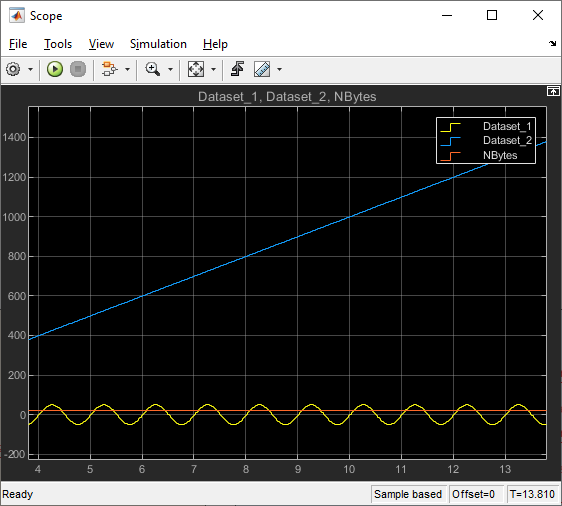

## Additional References

- [IO781 documentation and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io781)